clc,clear,close all

% f: 函数
f = @(x) 1./(1+25*x.^2);

% x_train: 插值点
x_train = -1:0.2:1;     %注意，这里 x_train 应该输入一个行向量

% y_train: 插值点处的函数值
y_train = f(x_train);

% x: 要预测的点
x0= -1:0.01:1;

% y: 预测的函数值
interpolation_function = myfun(x_train,y_train);
interpolation_function = matlabFunction(interpolation_function);
y = interpolation_function(x0);

% y_real: 真实的函数值
y_real = f(x0);

% interpolation_error: 误差. F 范数
interpolation_error = norm(y_real-y);

% 输出结果
disp('插值拟合结果为')
disp(y)
disp('真实值为')
disp(y_real)
disp('误差为')

误差为


disp(interpolation_error)

    3.9483



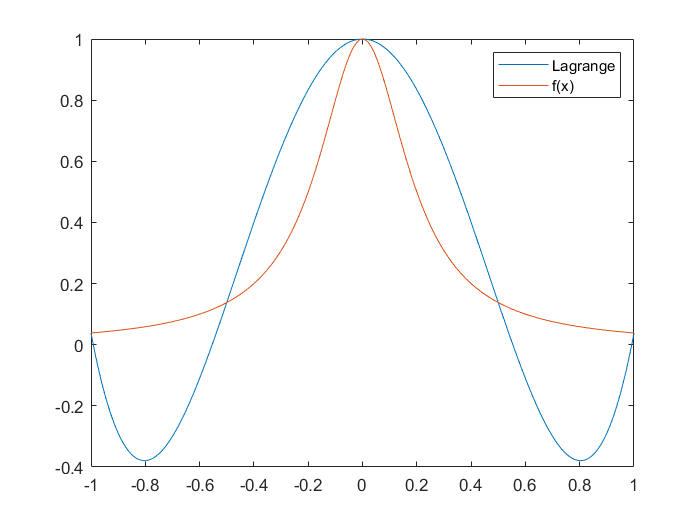

plot(x0,y)
hold on
plot(x0,y_real)